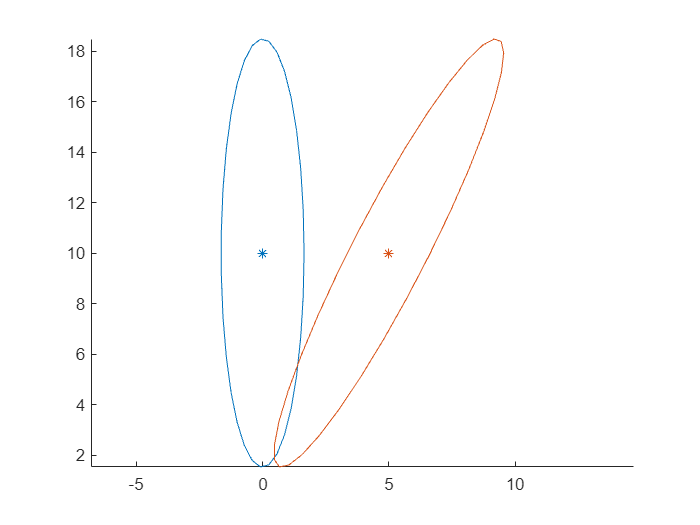

%1c
clear;
clc;
mu=[0;10];
sigma=[0.3,0;0,8];
A=[1,0.5;0,1];
b=[0;0];

[muz, sigmaz]=affineGaussianTransform(mu,sigma,A,b);
xy = sigmaEllipse2D(mu, sigma);
z = sigmaEllipse2D(muz,sigmaz);
%Now plot the generated points. You should see an elongated ellipse stretching from the top left corner to the bottom right. 
figure(1);
hold on
axis equal
h1 = plot(xy(1,:), xy(2,:));
h2 = plot(z(1,:), z(2,:));
%Set the scale of x and y axis to be the same. This should be done if the two variables are in the same domain, e.g. both are measured in meters.

%Also plot a star where the mean is, and make it have the same color as the ellipse.
plot(mu(1), mu(2), '*', 'color', h1.Color);
plot(muz(1), muz(2), '*', 'color', h2.Color);